# Gluon_6L3

From bilibili

# URDF

Open the file of `Gluon_6L3_v1_8_1.STEP`

- Start SolidWorks

- Seeting->Import->un checked "Enable 3D interconnect" (then  the assembly we import later will don't create the joints autonomously)

- Select the Cancel when the warning about the template appear as we open the model

- Assembly for every link (7 links including the base)

- Assembly

- Constraints: 

                (1) **Coincident        **origin point of the base        origin of the glob

                (2) For all rotating joints:

**                      Coincident       **surf                                       surf

                     ** Concentrit**        axis                                      axis

                (3) Constraint parallel for all top base surface of every sub assembly to specify the initial position

Create:

- rotate axis

- origin point of the coordinate systems

- coordinate systems

Tool->Tools->Export as URDF

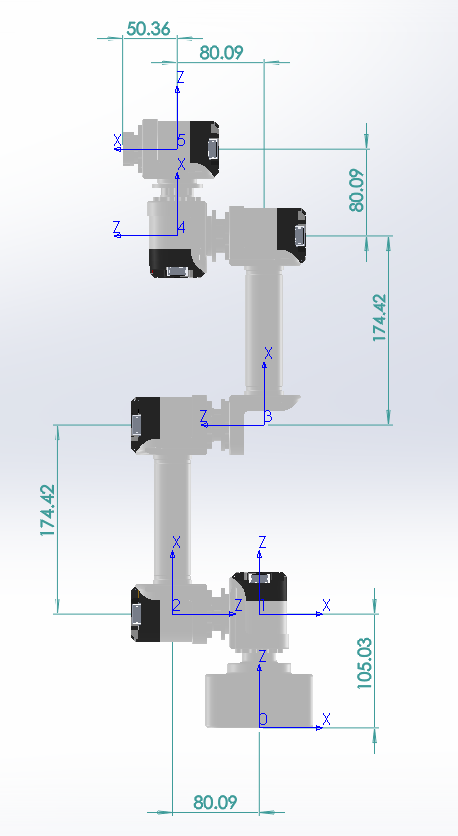

**Notice: **Acoording to MDH, the coordinate system is located the begining of the link, and the x-axis is point to the ending of the link.

close;
clc;
clear;


L(1) = Link([0 105.03 0 0],'modified');  %[theta(i), d(i), a(i-1), alpha(i-1)]
L(2) = Link([0 80.09 0 pi/2],'modified');
L(2).offset = pi/2;

L(3) = Link([0 -84.52 174.42 0],'modified');
L(4) = Link([0 84.52 174.42 0],'modified');
L(4).offset = pi/2;
L(5) = Link([0 80.09 0 pi/2],'modified');
L(6) = Link([0 50.36 0 pi/2],'modified');


robot = SerialLink(L);
robot.plot([pi 0 0 0 0 0]);
robot.teach;
robot.display;

 
robot = 
 
noname:: 6 axis, RRRRRR, modDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|     105.03|          0|          0|          0|
|  2|         q2|      80.09|          0|     1.5708|     1.5708|
|  3|         q3|     -84.52|     174.42|          0|          0|
|  4|         q4|      84.52|     174.42|          0|     1.5708|
|  5|         q5|      80.09|          0|     1.5708|          0|
|  6|         q6|      50.36|          0|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


Joints Properties:

Joints 1-3

- lower (rad): -3.14

- upper (rad): 3.14

- effort (N-mm): 150

- velocity (rad/s): 3.15

Joints 4-6

- lower (rad): -3.14

- upper (rad): 3.14

- effort (N-mm): 28

- velocity (rad/s): 3.2

# Simscape

close
clear
clc
robot = smimport('Gluon_6L3_v1_8_1.urdf');

Error using smimport_implementation
File Gluon_6L3_v1_8_1.urdf not found.

Error in smimport (line 175)
    [varargout{1:nargout}] = smimport_implementation(multibodyDescription, varargin{:});

# Robotics Toolbox & Simscape

验证二者

# Word Frame and Joint